# EE525 - Lab Project 2

Author: Grant Gallagher

Due: 10/15/2021

## Initialization

This section of code is used to clear the workspace of all variables and figures, so that the program can be run from scratch.

clc;    % Clear command window
clear;  % Clear all variables from workspace
clf;    % Clear all figures

## 1. Random Walk

Let $U_i$ for $i=1,2,\ldotp \ldotp \ldotp ,N$ be independent random variables with the same PMF


$$P_u \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{ll}
\frac{1}{2} & ,k=-1\\
\frac{1}{2} & ,k=1
\end{array}\right.$$


The random walk is a random process $X\left\lbrack n\right\rbrack$ with $X\left\lbrack n\right\rbrack =\sum_{i=0}^n U_i ,n=0,1,2,\ldotp \ldotp \ldotp \ldotp$ We assume that the random walk starts at time $n=0$.

- Simulate on the computer 10 realizations of this random process and plot them in one figure.

- Investigate the behavior of random walk when $n\to \infty$. Do this by **(1)** Finding the analytical solutions for $E\left\lbrack X\left\lbrack n\right\rbrack \right\rbrack$ and $\mathrm{var}\left(X\left\lbrack n\right\rbrack \right)$ and **(2) **Observing sample realizations using computer simulations/

- A *biased* random walk process is defined as $X\left\lbrack n\right\rbrack =\sum_{i=0}^n U_i ,$ where $U_i$ for $i=0,1,2,\ldotp \ldotp \ldotp ,N$ are independent random variables with the the same PMF


$$P_u \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{ll}
\frac{1}{4} & ,k=-1\\
\frac{3}{4} & ,k=1
\end{array}\right.$$


            Repeat steps 1 and 2 for *biased* random walk.

### 1.1

### 1.2

### 1.3

## 2. Weather Data Analysis

In this problem, we want to determine if the annual temperatures are increasing over the last 100 years using linear regression.

Collect the temperature data (consider both average temperature and max temperature) for the following three locations: Los Angeles, San Francisco, and Washington DC from the National Climate Data Center website ([https://www.ncdc.noaa.gov/cdo-web/](https://www.ncdc.noaa.gov/cdo-web/), choose a station from each city that has a long period of record).

- Assume $X\left\lbrack n\right\rbrack$ is the annual temperature in Los Angeles for year $n$. To confirm or dispute this supposition, assume that $\mu_X \left\lbrack n\right\rbrack =a\;n+b$ and determine if $a>n$, as would be the case if the means were increasing. Estimate $a$ by using least squares, that is to choose $a$ and $b$ that minimizes the least squares error $J\left(a,b\right)=\sum_{n=1}^N \left\lbrack {\left\lbrack x_n -\left(an+b\right)\right\rbrack }^2 \right\rbrack$.

- Plot the straight line derived in Step 1 to the sample data.

- Plot the least squares error sequence $e\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -\left(\hat{\;a} n+\hat{\;b} \right)$, and find the error varience.

- What's the predicted annual temperature in 2021 for Los Angeles bases on the past data and linear regression model?

- Repeat the above steps for the temperature data in the other two locations.

- What conclusions can one draw based on the above analyses.

### Los Angeles


$$J\left(a,b\right)=\sum_{n=1}^N \left\lbrack {\left\lbrack x_n -\left(an+b\right)\right\rbrack }^2 \right\rbrack$$


syms x
%% Import data
raw_data = readtable('raw_temp_data.csv');
tavg_la = get_weather(raw_data, 'LOS ANGELES DOWNTOWN USC, CA US')

[a, b] = least_squares(tavg_la);
plot_regression(tavg_la, a, b)
title('Los Angeles')
plot_errors(tavg_la, a, b)
title('Los Angeles')
varience(tavg_la(:,2))
t_2021 = a*(2021)+b

### San Francisco

tavg_sf = get_weather(raw_data, 'SAN FRANCISCO DOWNTOWN, CA US');
[a, b] = least_squares(tavg_sf);
plot_regression(tavg_sf, a, b)
title('San Francisco')

tavg_la = 	1.0e+03 *

    1.9090    0.0614
    1.9100    0.0631
    1.9110    0.0621
    1.9130    0.0625
    1.9210    0.0630
    1.9220    0.0625
    1.9230    0.0637
    1.9240    0.0635
    1.9250    0.0639
    1.9260    0.0651


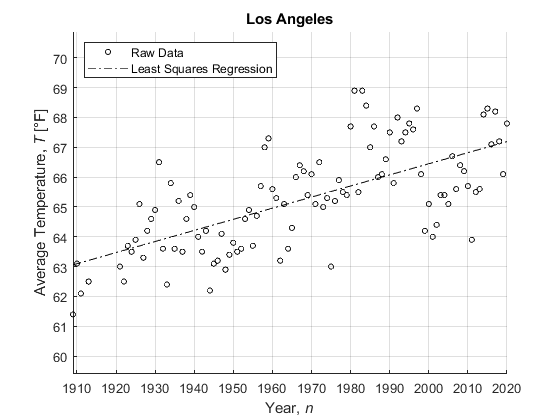

plot_errors(tavg_sf, a, b)
title('San Francisco')
varience(tavg_sf(:,2))
t_2021 = a*(2021)+b

## Washington DC

tavg_dc = get_weather(raw_data, 'NATIONAL ARBORETUM DC, MD US');

e = 104

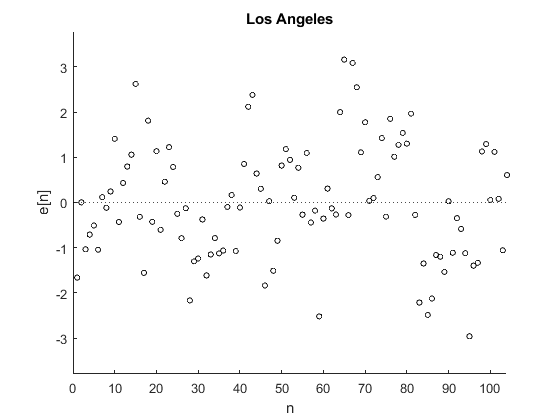

[a, b] = least_squares(tavg_dc);

plot_regression(tavg_dc, a, b)

ans = 2.9332

title('Washington DC')

t_2021 = 67.2304

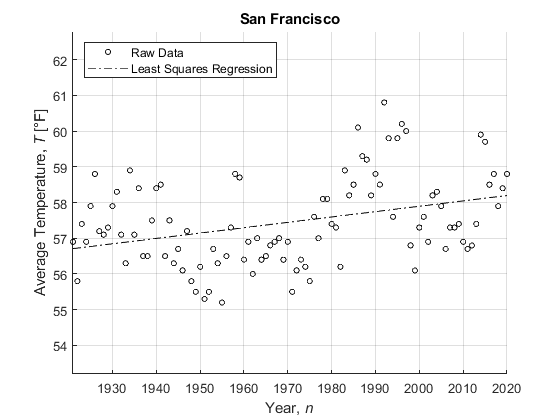

plot_errors(tavg_sf, a, b)
title('Washington DC')
varience(tavg_dc(:,2))

t_2021 = a*(2021)+b

### 2.6

e = 100

## Appendices

### Functions

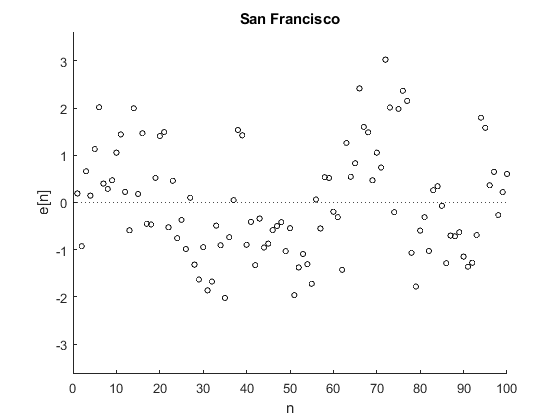

function temperature_history = get_weather(raw_data, location)

    years = raw_data.DATE(string(raw_data.NAME) == location);

ans = 1.5056

    temperatures = raw_data.TAVG(string(raw_data.NAME) == location);

t_2021 = 58.2100

 
    temperature_history = rmmissing([years temperatures]);
end

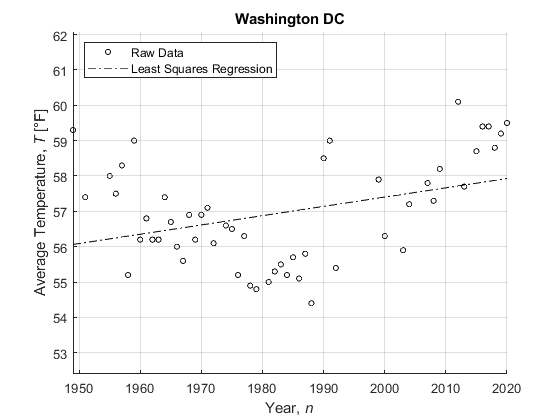

function [a, b] = least_squares(data)
    n = length(data);
    sx = sum(data(:,1));

    sy = sum(data(:,2));

e = 100

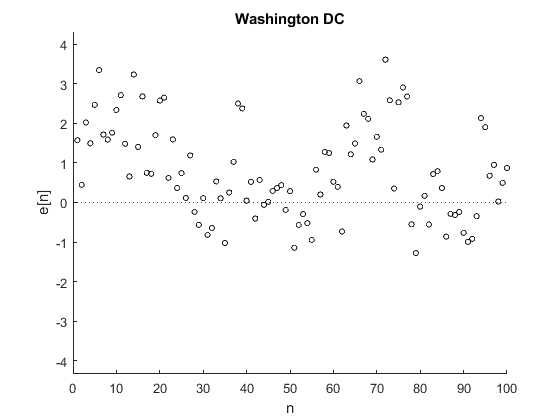

    sxy = sum(data(:,1).*data(:,2));

    sx2 = sum(data(:,1).^2);

ans = 2.2316

    
    a = (n*sxy-sx*sy) / (n*sx2-sx^2);

t_2021 = 57.9544

    
    b = (sy-a*sx) / n;
end

function plot_regression(data, a, b)
    syms x
    
    figure
    hold on
    plot(data(:,1), data(:,2),'o','Color',[0 0 0],'MarkerSize',4);
    fplot(a*x+b,'-.','Color',[0 0 0]);
    hold off
    grid on
    
    xlim([min(data(:,1)) max(data(:,1))]);
    ylim([min(data(:,2))-2 max(data(:,2))+2])

    legend('Raw Data','Least Squares Regression', 'Location','NorthWest');
    xlabel('Year, {\itn}')
    ylabel('Average Temperature, {\itT} [°F]')
    
end

function sigma_2 = varience(S)
    sigma_2 = sum((S-first_moment(S)).^2)/(length(S)-1);
end

function mu = first_moment(S)
    mu = sum(S)/length(S);
end

function plot_errors(data, a, b)
e = length(data)
for n = 1:length(data)
    e(n) = data(n,2)-(a*data(n,1)+b);
end
figure
hold on
plot(e,'o','Color',[0 0 0],'MarkerSize',4)
yline(0,':','Color',[0 0 0]);
hold off

xlim([0 length(e)]);
ylim([-max(abs(e))*1.2 max(abs(e))*1.2])

xlabel('n')
ylabel('e[n]')
end